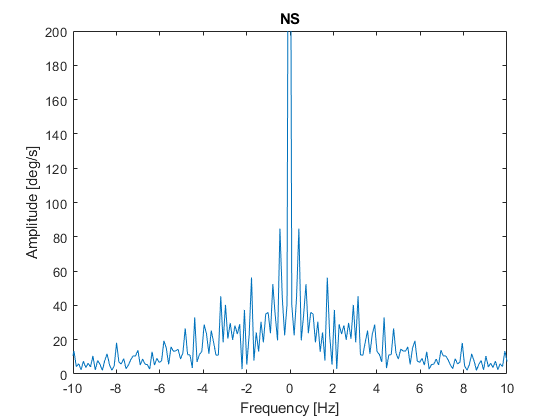

load("NS-Hallway-1.mat")
%stackedplot(AngularVelocity);
AngularVelocityTrim = AngularVelocity(round(0.2*end):round(0.4*end),:);
netAngularVelocityTrimNS = timetable(AngularVelocityTrim.Properties.RowTimes,vecnorm(AngularVelocityTrim.Variables,2,2));
%stackedplot(netAngularVelocityTrimNS);title('NS');figure()
plot_FT(netAngularVelocityTrimNS.Variables,100);
title('NS')
xlim([-10,10])
ylim([0,200])
xlabel('Frequency [Hz]')
ylabel('Amplitude [deg/s]')

disp(bandpower(netAngularVelocityTrimNS.Variables,100,[0,10]))

    0.4602


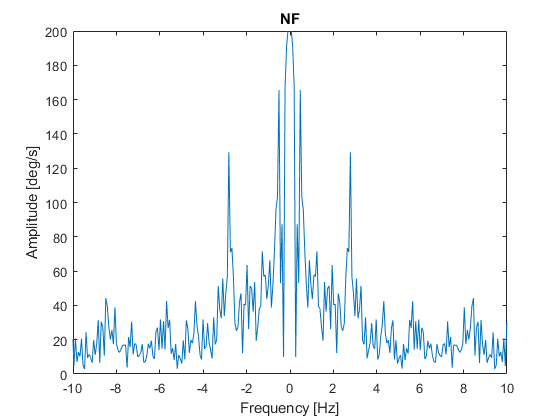

load("NF-Hallway-1.mat")
%stackedplot(AngularVelocity);
AngularVelocityTrim = AngularVelocity(round(0.33*end):round(0.55*end),:);
netAngularVelocityTrimNF = timetable(AngularVelocityTrim.Properties.RowTimes,vecnorm(AngularVelocityTrim.Variables,2,2));
%stackedplot(netAngularVelocityTrimNF);title('NF');figure()
plot_FT(netAngularVelocityTrimNF.Variables,100);
title('NF')
xlim([-10,10])
ylim([0,200])
xlabel('Frequency [Hz]')
ylabel('Amplitude [deg/s]')

disp(bandpower(netAngularVelocityTrimNF.Variables,100,[0,10]))

    1.0519


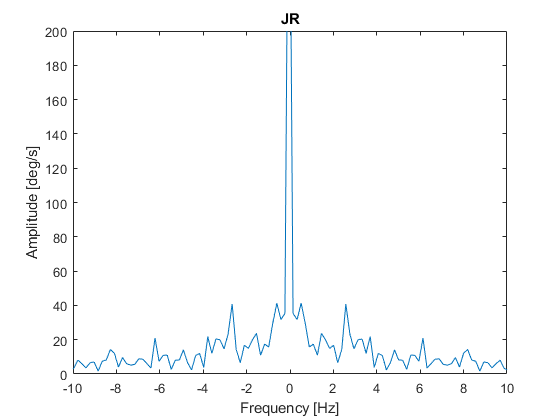

load("JR-Hallway-1.mat")
%stackedplot(AngularVelocity);
AngularVelocityTrim = AngularVelocity(round(0.33*end):round(0.45*end),:);
%stackedplot(AngularVelocityTrim);title('JR')
netAngularVelocityTrimJR = timetable(AngularVelocityTrim.Properties.RowTimes,vecnorm(AngularVelocityTrim.Variables,2,2));
%stackedplot(netAngularVelocityTrimJR);title('JR');figure()
plot_FT(netAngularVelocityTrimJR.Variables,100);
title('JR')
xlim([-10,10])
ylim([0,200])
xlabel('Frequency [Hz]')
ylabel('Amplitude [deg/s]')

disp(bandpower(netAngularVelocityTrimJR.Variables,100,[0,10]))

    0.6835
